%% Specific Concordance analysis from detected pulse indices

%  Guardabasso et al., Acta Endocrinol 1991;124:208-218.
%  Functions: interpulse_interval, pulse_concordance.

clear; clc; close all;

%% Parameters

rng(1);

dt     = 6;        % sampling interval (min)
N      = 31;       % samples per series
WINDOW = 3;        % time window (observations)
LAGS   = -8:8;     % lags tested (samples)
NSIM   = 20000;    % Monte Carlo simulations

%% Pulse indices

condition = 'OVX-GDX';   % 'Diestrus' | 'OVX-GDX' | 'OVX-E2'

switch condition
    case 'Diestrus'
        idxL = { [3 8 16 18 25 30], [4 8 12 17 20 25 29], [8 17 24], ...
                 [9 21 28], [6 11 16 24 26], [6 13 18], [6 24 29] };
        idxF = { [12 17 19 26 30], [3 5 7 10 14 20 23 25], [4 7 13 15 23], ...
                 [10 15 18 24], [5 9 22 24], [3 12 23 26], [12 27] };
        ids  = {'Ac33','Ac35','Ac45','Ac46','Ac60','Ac42','Ac48'};

    case 'OVX-GDX'
        idxL = { [5 8 10 14 21 23 26 29], [4 7 11 14 18 21 24 28], ...
                 [2 5 7 12 14 18 20 28 31], [4 6 10 14 16 21 24 29], ...
                 [2 9 13 17 19 22 26], [2 5 11 15 18 22 26 28 30] };
        idxF = { [2 4 8 10 13 17 23 27 29], [4 15 20 23 29], ...
                 [2 8 10 13 15 17 21 23 25 27 31], [2 6 9 17 24 28], ...
                 [3 7 9 12 17 19 21 25 27 30], [2 5 8 12 14 16 26 28 30] };
        ids  = {'Ac46 OVX','Ac48 OVX','Ac33 OVX+lowE2','Ac34 OVX+lowE2', ...
                'Ac36 OVX+lowE2','Ac45 OVX+lowE2'};

    case 'OVX_E2'
        idxL = { [6 9 16 19 26], [7 12 16 22 27], [3 7 12 18 25], ...
                 [4 12 14 20 24 30], [7 16 27] };
        idxF = { [4 9 18 21 23], [4 9 10 23 26], [4], ...
                 [2 6 12 18 24 29], [6 17 23] };
        ids  = {'Ac61','Ac63','Ac68','Ac72','Ac75'};

end

n_total = numel(ids);

%% Interpulse interval
rL = interpulse_interval(idxL, dt, 'LH');

--- Interpulse interval: LH ---
  subjects: 6 | events: 49 | intervals: 43
  mean 21.5 min | median 18.0 min | SD 8.6 min | range 12-48 min
  mean of subject means: 21.6 min (SD across subjects 1.3)



rF = interpulse_interval(idxF, dt, 'FSH');

--- Interpulse interval: FSH ---
  subjects: 6 | events: 50 | intervals: 44
  mean 22.1 min | median 18.0 min | SD 12.8 min | range 12-66 min
  mean of subject means: 24.2 min (SD across subjects 8.2)




fprintf('Pulses per 3 h: LH %.1f | FSH %.1f\n\n', ...
        mean(cellfun(@numel, idxL)), mean(cellfun(@numel, idxF)));

Pulses per 3 h: LH 8.2 | FSH 8.3



%% Group analysis
res = pulse_concordance(idxL, idxF, N, WINDOW, LAGS, NSIM, dt, ids, 1);

--- Mean SC (6 subjects) ---
  subject        nA   nB    SCmax    lag(min)
  Ac46 OVX        8    9   +0.0390       -18
  Ac48 OVX        8    5   +0.0415        +0
  Ac33 OVX+lowE2    9   11   -0.0063       -30
  Ac34 OVX+lowE2    8    6   +0.0415       -30
  Ac36 OVX+lowE2    7   10   +0.0287       +42
  Ac45 OVX+lowE2    9    9   -0.0063        -6

  Mean SCmax = +0.0123 at lag +0 min
  H0: p95 = 0.0092 | p99 = 0.0147  ->  p = 0.0229
  null baseline = -0.0226  (total 49 events in A, 50 in B)
  NON-RANDOM CONCORDANCE (p < 0.05)



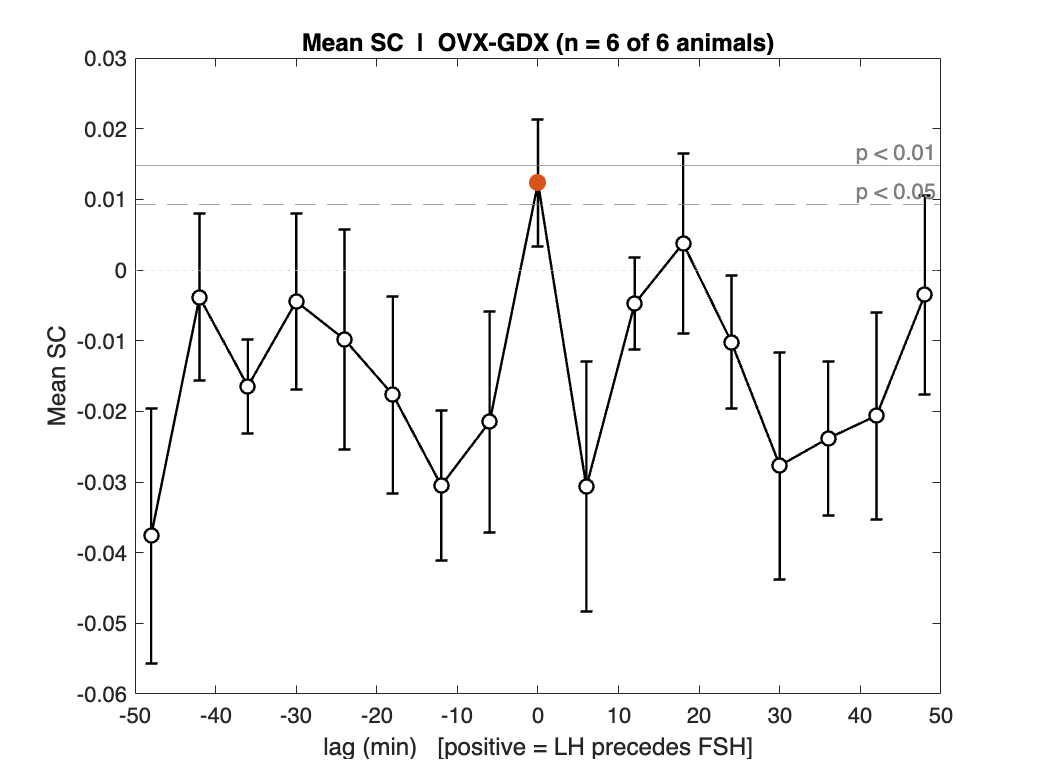

%% Figure
LAB_A = 'LH';  LAB_B = 'FSH';
x   = res.lags * res.dt;
sem = std(res.spectra, 0, 1, 'omitnan') ./ sqrt(size(res.spectra,1));

figure('Name','Mean SC', 'Color','w');

yline(res.p99, '-',  'p < 0.01', 'Color',[0.5 0.5 0.5], ...
      'LabelHorizontalAlignment','right', 'LabelVerticalAlignment','top', ...
      'FontSize',11);
yline(res.p95, '--', 'p < 0.05', 'Color',[0.5 0.5 0.5], ...
      'LabelHorizontalAlignment','right', 'LabelVerticalAlignment','top', ...
      'FontSize',11);
yline(0, ':', 'Color',[0.8 0.8 0.8]);
hold on;

% Error bars are descriptive (SEM across animals); significance comes from
% the Monte Carlo null, i.e. the two horizontal lines.
errorbar(x, res.mean_spectrum, sem, '-o', ...
         'Color','k', 'LineWidth',1.2, ...
         'MarkerSize',7, 'MarkerFaceColor','w', 'MarkerEdgeColor','k', ...
         'CapSize',6);

if res.mean_SCmax > res.p95
    plot(res.lag_min, res.mean_SCmax, 'o', 'MarkerSize',8, ...
         'MarkerFaceColor',[0.85 0.33 0.1], 'MarkerEdgeColor',[0.85 0.33 0.1]);
end

xlabel(sprintf('lag (min)   [positive = %s precedes %s]', LAB_A, LAB_B), ...
       'FontSize',12);
ylabel('Mean SC', 'FontSize',12);
title(sprintf('Mean SC  |  %s (n = %d of %d animals)', ...
              condition, res.n_subjects, n_total), 'FontSize',13);

xlim([min(x)-2  max(x)+2]);
set(gca, 'FontSize',11, 'Box','on', 'TickDir','in', 'Layer','top');
grid off;


% ylim([-0.05 0.04])